# Práctica 3. Sistemas dinámicos continuos

## Identificación del alumno

Nombre: Alfredo

Apellidos: Robledano Abasolo

Grupo:  B

DNI: 51504163X                           Problemas nº: 4     y  nº: 5

## Instrucciones

- Tiene el tiempo de clase para realizar la práctica

- Rellena tu identificación. No rellenar correctamente la identificación restará 1.0 puntos en la calificación final.

- Identifica los problemas a resolver. No borres el resultado.

- Rellena los números de los dos problemas en el lugar adecuado de tu identificación.

- Nombra el archivo de la forma indicada. Nombrarlo mal resta 0.5 puntos a la calificación final.

- Lee la rúbrica para conocer cómo se va a corregir la práctica.

- Cuando tengas la seguridad de saber lo que se te va a pedir y cómo se te va a calificar, continúa en el punto siguiente.

- Resuelve los dos problemas. No cometas faltas de ortografía. Las confusiones debidas al uso del teclado no se considerarán como tales.

- Vuelve a leer todas las instrucciones. Comprueba que todo es correcto.

- Repasa la práctica. Corrige lo que sea necesario. Incluyendo faltas de ortografía o de escritura.

- Sube el archivo al lugar habilitado para ello en el Canvas.

## Identificar los problemas a resolver

NO MODIFIQUE NADA DEL SIGUIENTE CÓDIGO

**Corra el programa siguiente e introduce tu DNI ****cuando te lo pida****:**

clear, clc
DNIt = inputdlg('INTRODUCIR EL DNI SIN LETRA NI PUNTOS');
if isempty(cell2mat(DNIt))
    errordlg('No puede dejar el DNI vacío', 'Error en la entrada')
    return
end
rng(str2num(cell2mat(DNIt)))
prob1 = ceil(5*rand);
prob2 = ceil(5*rand);

if prob1 == prob2
    while prob2 == prob1
        prob2 = ceil(5*rand);
    end
end

fprintf(1,'DNI = %s \n', cell2mat(DNIt))

DNI = 51504163 


fprintf(1,'Tiene que resolver los problemas: \n') 

Tiene que resolver los problemas: 


fprintf(1,'     Problema %1.0f  \n', prob1)

     Problema 4  


fprintf(1,'     Problema %1.0f  \n', prob2)

     Problema 5  


Instrucciones

## Entrega

Nombra el archivo como: **Apellido1Apellido2Nombre.zip** que contenga este fichero (con su nombre) y todos aquellos ficheros auxiliares que necesita para completar la práctica, incluidos los modelos de Simulink. Súbelo al enlace de la tarea. Nombrar mal el archivo restará 0.5 puntos en la calificación final.

Instrucciones

## Rúbrica

- Cada problema vale 4 puntos. Para ello, tiene que estar perfectamente resuelto, con explicaciones claras, sin líneas de código superfluas; bien explicado. Los textos con los resultados se deben mostrar por las funciones que tiene MATLAB para ello. Las figuras tienen que ser profesionales.

- 1 punto adicional por la limpieza, el orden y la claridad de las exposiciones y figuras.

## Problema 1				

Se sabe que la tasa de crecimiento de una determinada población de virus es directamente proporcional al número de virus existentes. Se realiza un cultivo en laboratorio, introduciendo 2.5 millones de virus en un recipiente. Se observa que la población se duplica cada 3 horas. Calcular la población existente al cabo de 11 horas. 

a) resolver el problema analíticamente.

b) construir el modelo en Simulink y verificar el resultado.		

### Solución		

## Problema 2

La población en el continente asiático en el año 2000 era de aproximadamente 4830 millones de personas y, en aquel momento, crecía a un ritmo de un 1.73% por año. Suponiendo que el crecimiento de la población se rigiera por el modelo exponencial, calcular el valor estimado de la población en dicho continente en el año 2025. 

a) resolver el problema analíticamente.

b) construir el modelo en Simulink y verificar el resultado.	

### Solución		

## Problema 3	

En un laboratorio se cultivan virus a razón de $v$ virus por día. La densidad de estos depende de la tasa de muerte $m$ de estos por día. Hacer una formulación razonable de este fenómeno, encontrar su solución general y  discutir dicha solución.

### Solución

## Problema 4

Considere la siguiente ecuación diferencial:

a) construya el modelo en Simulink.

b) trace las gráficas de $y$ con cada una de sus derivadas	

c) si el modelo es estable, estudiar analíticamente su estabilidad. En caso contrario, ¿depende la estabilidad de las condiciones iniciales?

### Solución

a) Construya el modelo en Simulink.

- Véase Problema4.slx

b) Trace las gráficas de $y$ con cada una de sus derivadas

Limpieza del entorno de trabajo

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

En este livescript definiremos el modelo, es decir, definiremos sus ecuaciones y constantes, para su posterior análisis.

Ecuación del modelo:

Despejamos la derivada de mayor orden


$$y^{\left(4\right)} =-3{y^{\prime } }^{\prime } +\sin \left(t\right)y^{\prime } -8y+t^2$$


Constantes del modelo:


$$\begin{array}{l}
y\left(0\right)=1\\
y^{\prime } \left(0\right)=2\\
{y^{\prime } }^{\prime } \left(0\right)=3\\
{{y^{\prime } }^{\prime } }^{\prime } \left(0\right)=4\\
t_{inicial} =0\;s\\
t_{final} =50\;s
\end{array}$$


Una vez definido el modelo se configura en el archivo sim_utils.m y se toman de este las configuraciones:

[cfg, model_names, constants] = sim_utils();

Al final de este livescript se encuentra la definición de la función sim_config, función que simula el modelo para una configuración de solver almacenada en cfg.solver (véase sim_utils.m)

signals = sim_config(model_names{1}, cfg.solver{1});
num_signals = numElements(signals);

Se dibuja la señal obtenida de la simulación respecto de cada derivada

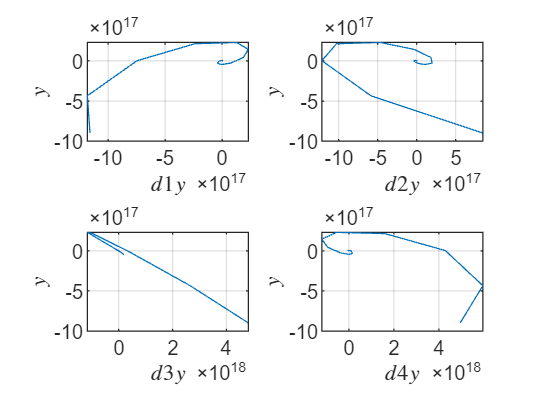

y = signals{1}.Values.Data;
hold on
for i=2:num_signals
    signal = signals{i};
    diy = signal.Values.Data;
    subplot(2, 2, i-1)
    plot(diy, y, cfg.plot{1}{:}, DisplayName=signal.Name)
    xlabel(sprintf('$%s$', signal.Name), cfg.xlabel{1}{:})
    ylabel('$y$', cfg.ylabel{1}{:})
    grid
end
hold off

Se observa que la señal varía cada vez en mayor proporción (su crecimiento y decrecimiento)

c) Si el modelo es estable, estudiar analíticamente su estabilidad. En caso contrario, ¿depende la estabilidad de las condiciones iniciales?

Echemos un vistazo a la solución númerica que hemos obtenido y(t)

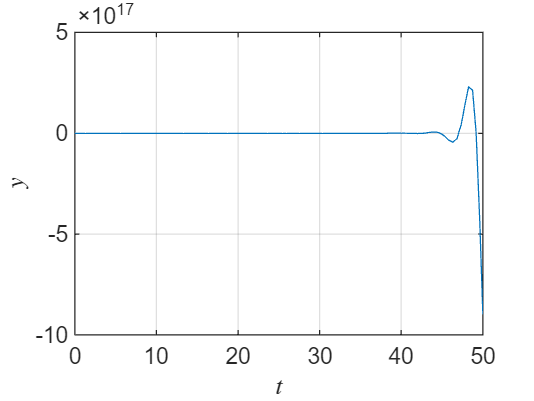

y = signals{1}.Values.Data;
t = signals{1}.Values.Time;
figure
plot(t, y, cfg.plot{1}{:}, DisplayName=signal.Name)
xlabel('$t$', cfg.xlabel{1}{:})
ylabel('$y$', cfg.ylabel{1}{:})
grid

El modelo no es estable, analíticamente podemos estudiar cuando la variación, es decir, las derivadas se hacen cero.


$$y^{\prime } =0={y^{\prime } }^{\prime } ={{y^{\prime } }^{\prime } }^{\prime } =y^{\left(4\right)}$$


Obteniéndose:


$$y=\frac{t^2 }{8}$$


Función claramente no acotable, no pudiendo encontrar estabilidad. Y por otro lado no influyen las condiciones iniciales.

## Problema 5

En el problema del estudio del sistema de amortiguación de un coche, suponga que debemos añadir el efecto de la fricción de la rueda con el asfalto. Modifique las ecuaciones, construya el modelo con Simulink y pruebe el resultado con la entrada en escalón unitario.

### Solución	

En este livescript definiremos el modelo, es decir, definiremos sus ecuaciones y constantes. Para su posterior análisis.

Ecuaciones del modelo sin fricción:


$$\begin{array}{l}
F_k =K_c \left(x-y\right)\\
F_c =C_c \left(x^{\prime } -y^{\prime } \right)\\
F_r =K_r \left(y-r\right)
\end{array}$$


Para añadir fricción lo que hacemos es incluir una fuerza adicional aplicada sobre la rueda, que le ayuda a agarrarse al asfalto, y por tanto rodar con menor deslizamiento:


$$F_{\mu } =K_{\mu } \;r$$


Ley de Newton


$$\begin{array}{l}
F=m\;a\\
m_c \;{x^{\prime } }^{\prime } =-F_k -F_c \\
m_r {y^{\prime } }^{\prime } =F_k +F_c -F_r -F_{\mu } 
\end{array}$$


Sustituyendo


$$\begin{array}{l}
{x^{\prime } }^{\prime } =-\frac{C_c }{m_c }x^{\prime } +\frac{C_c }{m_c }y^{\prime } -\frac{K_c }{m_c }x+\frac{K_c }{m_c }y=\\
\frac{1}{m_c }\left(C_c \left({-x}^{\prime } +y^{\prime } \right)+K_c \left(-x+y\right)\right)\\
{y^{\prime } }^{\prime } =\frac{C_c }{m_r }x^{\prime } -\frac{C_c }{m_r }y^{\prime } +\frac{K_c }{m_r }x-\frac{K_c }{m_r }y-\frac{K_r }{m_r }y+\frac{K_r }{m_r }r-\frac{K_{\mu } }{m_r }r=\\
\frac{1}{m_r }\left(C_c \left(x^{\prime } -y^{\prime } \right)+K_c \left(x-y\right)+K_r \left(-y+r\right)-K_{\mu } \;r\right)
\end{array}$$


Limpieza del entorno de trabajo

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

Habiendo definido el modelo se configura en el archivo sim_utils.m (véase sim_utils.m) y se toman de este las configuraciones:

[cfg, model_names, constants] = sim_utils();

Esto es: configuraciones de solver, plot, scatter, xlabel, ylabel, title, junto con los nombres y las condiciones iniciales de los modelos.

#### Simulación

Al final de este livescript se encuentra la definición de la función sim_config, función que simula el modelo para una configuración de solver almacenada en cfg.solver (véase sim_utils.m)

signals = sim_config(model_names{2}, cfg.solver{2});
num_signals = numElements(signals);

Se dibuja cada señal

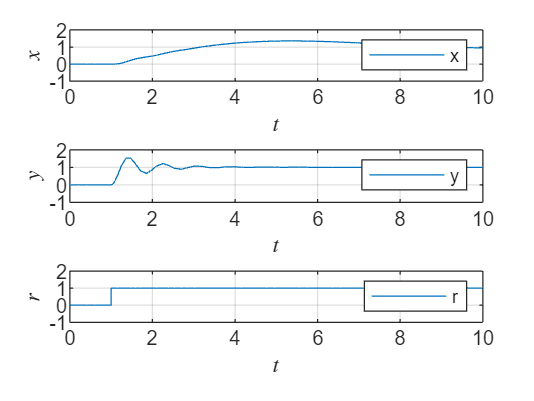

for i=1:num_signals
    signal = signals{i};
    t = signal.Values.Time;
    y = signal.Values.Data;
    subplot(3, 1, i)
    plot(t, y, cfg.plot{1}{:}, DisplayName=signal.Name)

    xlim([t(1), t(end)])
    ylim([-1, 2])
    xlabel('$t$', cfg.xlabel{1}{:})
    ylabel(sprintf('$%s$', signal.Name), cfg.ylabel{1}{:})
    legend(cfg.legend{1}{:})
    grid on
end

## Funciones disponibles para todas las secciones:

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

#### Decorador de la función sim de MATLAB

Esta función ejecuta la función sim, tras establecer los parámetros del solver.

function signals = sim_config(model_name, solver_config)
% Simulate a model with a custom solver
% Returns Dataset with signal of each Out1 block
% Note: In a signal, for multiple conditions, multiple values
% INPUTS
% ------------------------------------------
% model_name = string
% solver_config = cell array
%
% OUTPUTS
% ------------------------------------------
% signals = Simulink.SimulationData.Dataset

load_system(model_name)
% open_system(model_name) will also open it

% Set solver parameters
set_param(model_name, solver_config{:})

% Simulation Output
sim_data = sim(model_name);
signals = sim_data.yout; % Dataset container of signals
end

#### Consideraciones adicionales Simulink

Se utiliza el bloque Out1 para cada señal debido a que:

- No usaremos bloques Bus para no formatear los nombres, ejemplo: MATLAB transforma '+' a '_'

- No usaremos bloques To Workspace para iterar más fácil, iteramos el contenido de .yout

- Es posible el manejo de múltiples condiciones iniciales sin problema

#### Scripts adicionales

Para obtener cada señal se puede usar: 

% signals{index}
% signals.getElement('signal_name')

Los valores de una señal se encuentran en el campo Values

% signals{index}.Values.Data
% signals{index}.Values.Time
% signals{index}.Values.Name

Inicio y fin de una señal

% sim_data = sim_config(model_name, solver)
% signals = sim_data.yout
%
% start_value = signals{1}.Values.Data(1);
% end_value = signals{1}.Values.Data(end);

Máximo y mínimo de una señal

% sim_data = sim_config(model_name, solver)
% signals = sim_data.yout
%
% [signal_max, index_max] = max(signals{1}.Values.Data);
% point_max = [signals{1}.Values.Time(index_max), signal_max];
%
% [signal_min, index_min] = min(signals{1}.Values.Data);
% point_min = [signals{1}.Values.Time(index_min), signal_min];

Media de una señal

% sim_data = sim_config(model_name, solver)
% signals = sim_data.yout
%
% signal_mean = mean(signals{1}.Values.Data)

Autor: Alfredo Robledano Abasolo 3ºB Ingeniería Matemática UFV (2023-2024)